% TASK 2
% Start of script. clear any remaining variables from previous script runs.
clear

% Number of samples used for testing (number of elements of the data vector).
N =5000

N = 5000

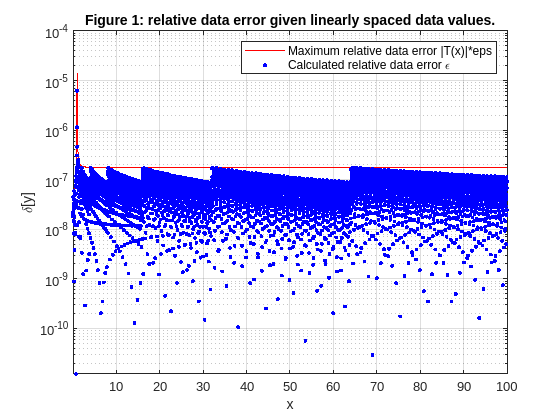

% initializing vectors of data:
% x:  vector of linearly spaced data values.
% xl: vector of logarithmically spaced data values.
x = linspace(10^-2, 10^2, N);
xl = logspace(-2, 2, N);

% initialization of error corrupted data vectors. Data corruption is done
% by converting from "double" representaion (default in MATLAB), to "single" representation.
x_err = double(single(x));
xl_err = double(single(xl));

% Defining functions f(x) and T(x). f(x) is the function given originally in the
% assignment A description. It is the function for which we are interested
% in finding the coefficient of data error propogation T(x). T(X) was
% derived in task 1 of assignment A.
f = @(x) (atan(x)./x.^2) - x.^3;
T = @(x) (x./(1+x.^2) -2*atan(x) -3*x.^5)./(atan(x)-x.^5);

% Calculating the vector of non-error-corrupted values of the
% results of f(x) (here named y), as well as the vector of error-corrupted
% values of f(x) (here named y_err). All the operations mentioned
% are here done for the vector of linearly spaced data values x.
y = f(x);
y_err = f(x_err);

% The same set of operations as the last step, but here done for the vector
% of logarithmically spaced data values xl.
yl = f(xl);
yl_err = f(xl_err);

% Calulating the relative error in the result using the definition for
% relative error. dy is the error in y_err, dyl is the error in yl_err. The
% reason for taking the absolute value of the error is because we are
% interested only in the error magnitude.
dy = abs((y_err-y)./y);
dyl = abs((yl_err-yl)./yl);

% Calculating the maximum relative error due to rounding (the division by
% two here is becuase the built-in eps returns the minimum space between
% two consecutive numbers, which is twice the maximum error due to rounding.
epssin = eps("single")/2;

% Calculating the vector containing N samples of the function describing 
% the maxinum possible relative error approximation. t is the vector of samples 
% given the linearly spaced data values, tl is the vector of samples given the
% logarithmically spaced data values.
t = abs(T(x))*epssin;
tl = abs(T(xl))*epssin;

% Code for the generation of figure 1.
figure(1);
plot(x,t,"r-");
hold on;grid on
axis([0.01,100,-inf,1e-4])
plot(x,dy,"b.");
xlabel('x');
ylabel('\delta[y]');
legend("Maximum relative data error |T(x)|*eps","Calculated relative data error \epsilon")
title("Figure 1: relative data error given linearly spaced data values.")
yscale log;hold off;

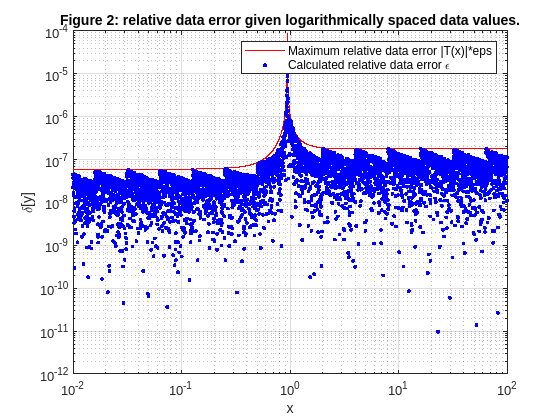


% Code for the generation of figure 2.
figure(2);
loglog(xl, tl, 'r-');
hold on;grid on;
loglog(xl, dyl, ".b");
xlabel('x');
ylabel('\delta[y]');
legend("Maximum relative data error |T(x)|*eps","Calculated relative data error \epsilon")
title("Figure 2: relative data error given logarithmically spaced data values.")
hold off;